addpath('./nifti_tools/')
addpath('./data/')

%% Load one subject's data
dataPath = 'data/case_1/';

% Load the 4D multi-echo image (x, y, z, TE)
d = load_nii([dataPath 'case01-qt2_reg.nii.gz']);
img = double(d.img);          % 4D array: [x, y, z, nTEs]

% Load echo times
TEs = load([dataPath 'case01-TEs.txt']);   % in milliseconds

% Load the brain mask (1 = brain, 0 = background)
m = load_nii([dataPath 'case01-mask.nii.gz']);
mask = logical(m.img);

% Load tissue segmentation
%   typically: 1=CSF, 2=GM, 3=WM  (check your specific dataset)
s = load_nii([dataPath 'case01-seg.nii.gz']);
seg = s.img;

fprintf('Image size: %d x %d x %d, with %d echo times\n', size(img));

Image size: 96 x 96 x 55, with 19 echo times


fprintf('Echo times (ms): '); disp(TEs')

Echo times (ms):     19
    21
    23
    25
    28
    31
    34
    37
    40
    44
    48
    52
    57
    67
    80
    95
   110
   130
   150



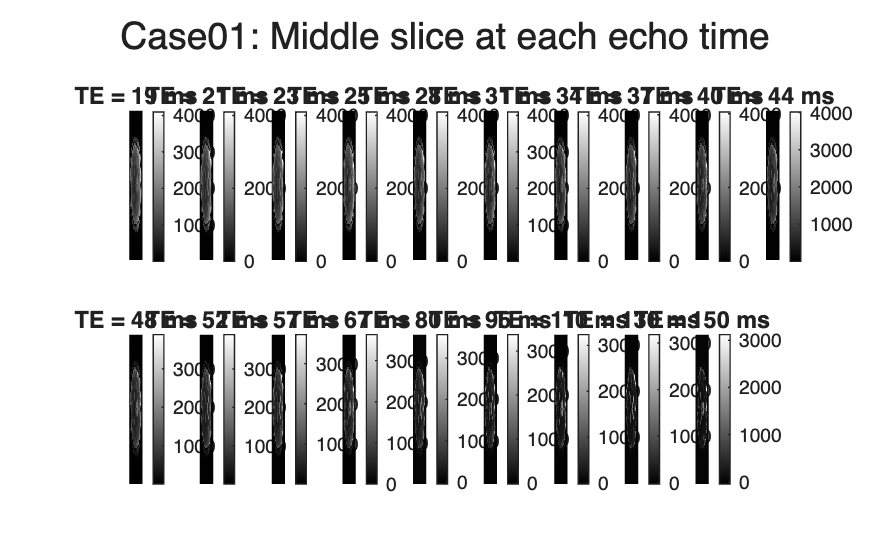

%% Plot 1: Show the brain at each echo time (middle slice)
midSlice = round(size(img, 3) / 2);

figure;
nTE = length(TEs);
for i = 1:nTE
    subplot(2, ceil(nTE/2), i);
    imagesc(img(:,:,midSlice,i));
    colormap gray; axis off; colorbar;
    title(sprintf('TE = %.0f ms', TEs(i)));
end
sgtitle('Case01: Middle slice at each echo time');

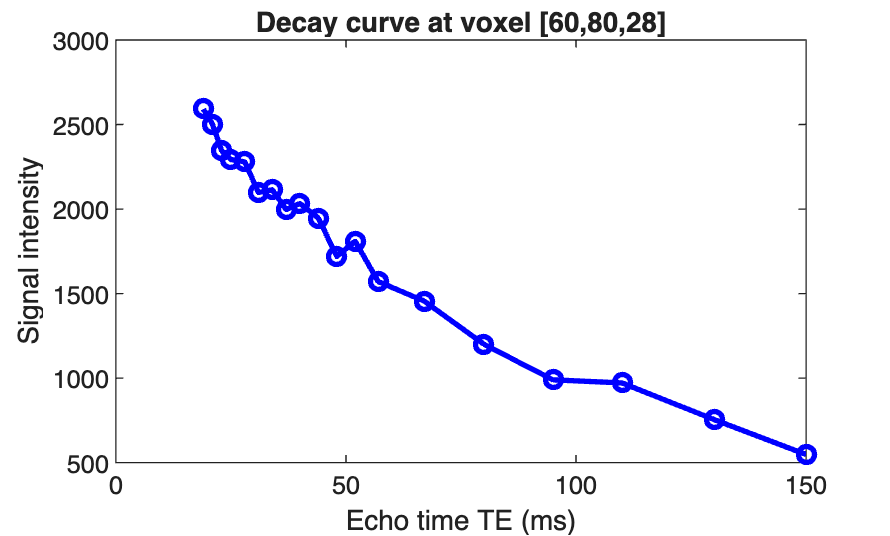


%% Plot 2: Time-intensity decay curve for a single voxel
% Pick a voxel roughly in white matter (adjust x,y,z for your data)
x = 60; y = 80; z = midSlice;

signal = squeeze(img(x, y, z, :));   % signal at each TE

figure;
plot(TEs, signal, 'bo-', 'LineWidth', 2);
xlabel('Echo time TE (ms)'); ylabel('Signal intensity');
title(sprintf('Decay curve at voxel [%d,%d,%d]', x, y, z));

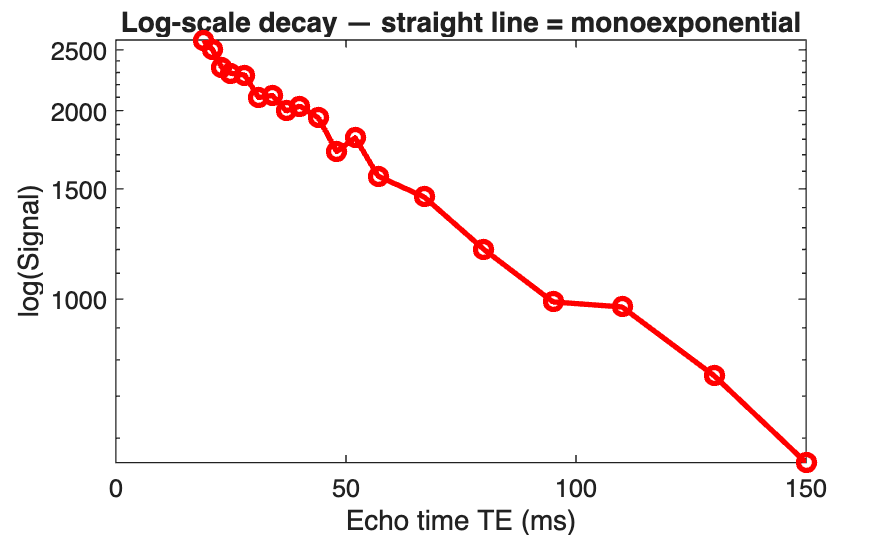


% Also plot on log scale — should be a straight line if monoexponential
figure;
semilogy(TEs, signal, 'ro-', 'LineWidth', 2);
xlabel('Echo time TE (ms)'); ylabel('log(Signal)');
title('Log-scale decay — straight line = monoexponential');

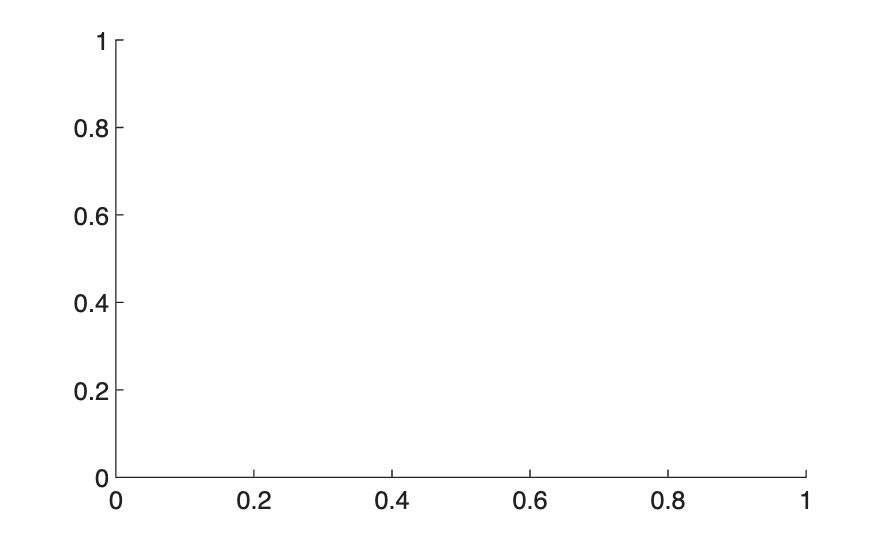


%% Plot 3: Mean decay curves per tissue class
figure; hold on;

colors = {'b','r','g'};
labels = {'CSF','GM','WM'};

for tissue = 1:3
    voxels = find(seg == tissue & mask);   % masked voxels of this tissue
    % Extract signal for all these voxels across TEs
    meanSig = zeros(1, nTE);
    for t = 1:nTE
        vol = img(:,:,:,t);
        meanSig(t) = mean(vol(voxels));
    end
    semilogy(TEs, meanSig, colors{tissue}, 'LineWidth', 2, 'DisplayName', labels{tissue});
end

Index exceeds the number of array elements. Index must not exceed 506880.


xlabel('TE (ms)'); ylabel('Mean signal (log scale)');
legend; title('Mean decay curves by tissue type');



addpath('./nifti_tools/')
dataPath = 'data/case_1/';

%% Load data
d = load_nii([dataPath 'case01-qt2_reg.nii.gz']);
img = double(d.img);

TEs = load([dataPath 'case01-TEs.txt']);

m = load_nii([dataPath 'case01-mask.nii.gz']);
mask = logical(m.img);

s = load_nii([dataPath 'case01-seg.nii.gz']);
seg = s.img;

fprintf('Image size: %d x %d x %d, with %d echo times\n', size(img));

Image size: 96 x 96 x 55, with 19 echo times


fprintf('Echo times (ms): '); disp(TEs')

Echo times (ms):     19
    21
    23
    25
    28
    31
    34
    37
    40
    44
    48
    52
    57
    67
    80
    95
   110
   130
   150



disp('Seg unique values:'); disp(unique(seg(:))')

Seg unique values:
  Columns 1 through 3276

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

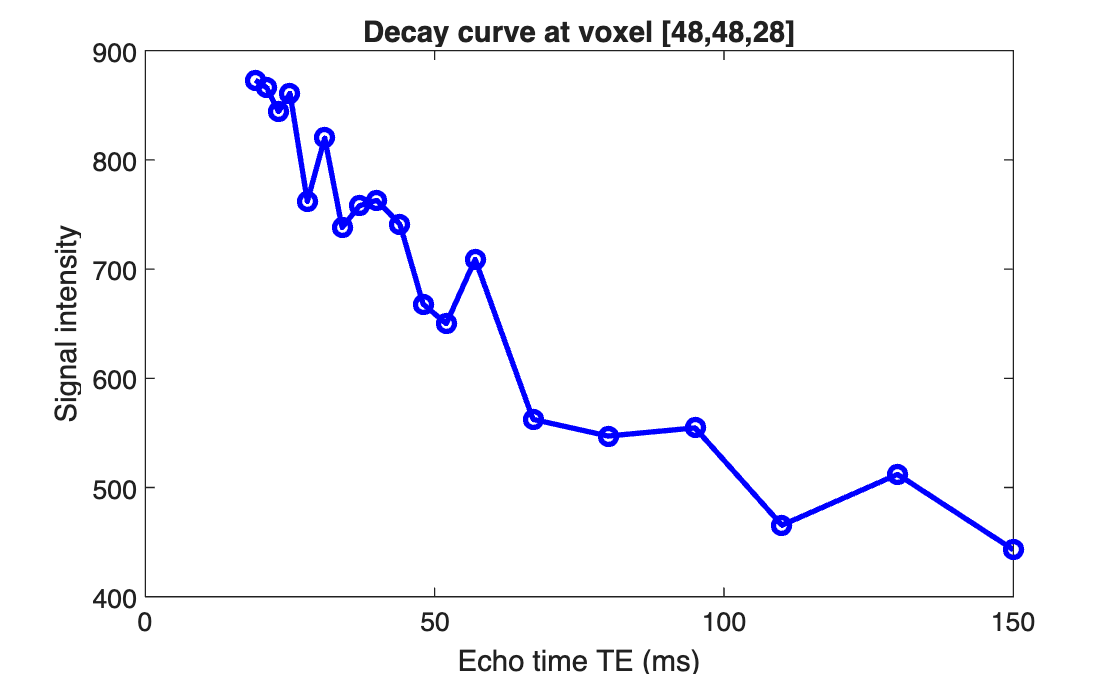


%% Plot 1: Brain at each echo time
midSlice = round(size(img, 3) / 2);  % = 27
nTE = length(TEs);

figure;
for i = 1:nTE
    subplot(2, ceil(nTE/2), i);
    imagesc(img(:,:,midSlice,i));
    colormap gray; axis off; colorbar;
    title(sprintf('TE = %.0f ms', TEs(i)));
end
sgtitle('Case01: Middle slice at each echo time');

%% Plot 2: Single voxel decay curve
% Safe coordinates within 96x96x55
x = 48; y = 48; z = midSlice;

signal = squeeze(img(x, y, z, :));

figure;
plot(TEs, signal, 'bo-', 'LineWidth', 2);
xlabel('Echo time TE (ms)'); ylabel('Signal intensity');
title(sprintf('Decay curve at voxel [%d,%d,%d]', x, y, z));

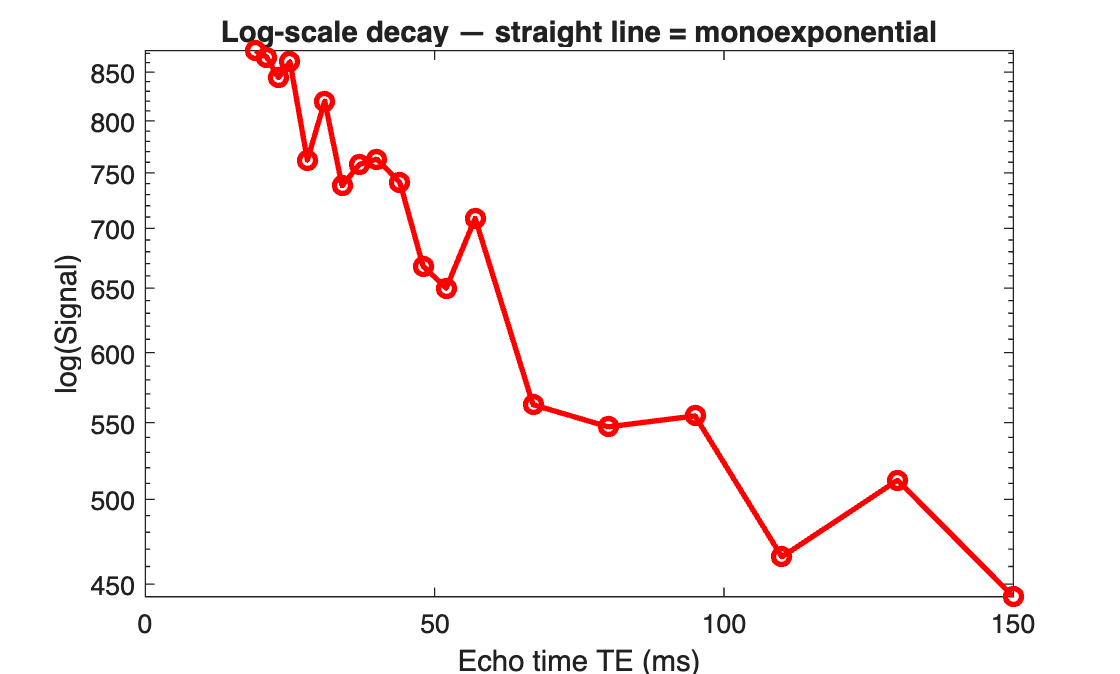


figure;
semilogy(TEs, signal, 'ro-', 'LineWidth', 2);
xlabel('Echo time TE (ms)'); ylabel('log(Signal)');
title('Log-scale decay — straight line = monoexponential');

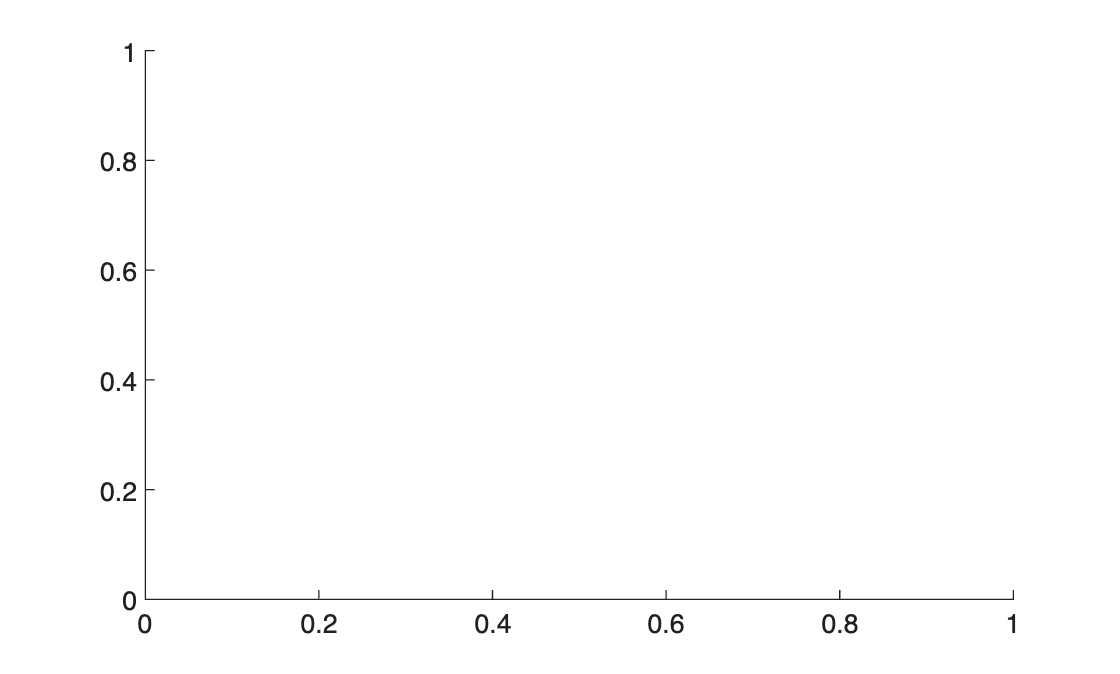


%% Plot 3: Mean decay curves per tissue class
figure; hold on;

colors = {'b','r','g'};
labels = {'CSF','GM','WM'};

for tissue = 1:3
    voxels = find(seg == tissue & mask);
    meanSig = zeros(1, nTE);
    for t = 1:nTE
        vol = img(:,:,:,t);
        meanSig(t) = mean(vol(voxels));
    end
    semilogy(TEs, meanSig, colors{tissue}, 'LineWidth', 2, 'DisplayName', labels{tissue});
end

Index exceeds the number of array elements. Index must not exceed 506880.

xlabel('TE (ms)'); ylabel('Mean signal (log scale)');
legend; title('Mean decay curves by tissue type');


Error using load_nii_hdr (line 32)
Cannot find file "qt2.nii".

Error in load_nii (line 129)
   [nii.hdr,nii.filetype,nii.fileprefix,nii.machine] = load_nii_hdr(filename);
   ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^